% Clear Workspace
clear all
clc

% Read STL File
% stl1 = stlread("Test Objects\cubeWithHole.STL");
% stl1 = stlread("Test Objects\cylinder.STL");
stl1 = stlread("Test Objects\Case.STL");
% stl1 = stlread("Test Objects\box.STL");
% stl1 = stlread("Test Objects\keys.STL");

trisurf(stl1)
hold on

% Create UniformSliceGeneratorObject
sliceHeight = 0.5;
uSGO1 = FlatUniformSliceGenerator(stl1, sliceHeight)

uSGO1 =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [750×3 double]
       numOfElements: 750
              points: [371×3 double]
      sliceThickness: 0.5000
           slicePath: []
           slicerTol: 1.0000e-05


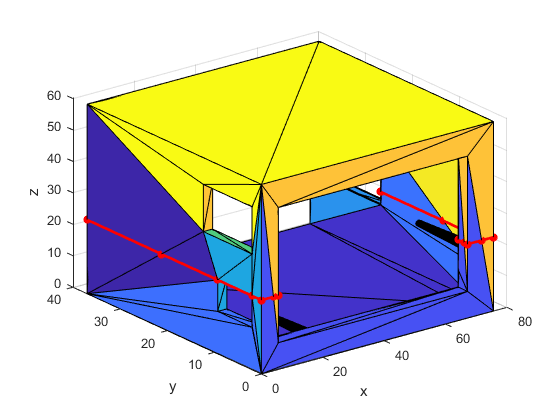


% Manual Slice for Debugging - Comment out if not used.
test = uSGO1.slice(23.5);
for j = 1:max(test(:,4))

    pathPlotPoints = test(test(:,4) == j,:);
    plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r*','LineWidth',2);
    hold on

end
xlabel('x')
ylabel('y')
zlabel('z')

% Generate
view(3);

figure(3)
uSGO1.generateSlices()

ans =   FlatUniformSliceGenerator with properties:

                 obj: []
    connectivityList: [750×3 double]
       numOfElements: 750
              points: [371×3 double]
      sliceThickness: 0.5000
           slicePath: [8381×4 double]
           slicerTol: 1.0000e-05


op = uSGO1.getSlicePath()

op =    75.6000         0         0    1.0000
   75.6000   37.0000         0    1.0000
         0   37.0000         0    1.0000
         0         0         0    1.0000
   75.6000         0         0    1.0000
   75.1017         0    0.5000    1.0000
   75.5177         0    0.5000    1.0000
   75.6000         0    0.5000    1.0000
   75.6000    0.5688    0.5000    1.0000
   75.6000    0.9566    0.5000    1.0000


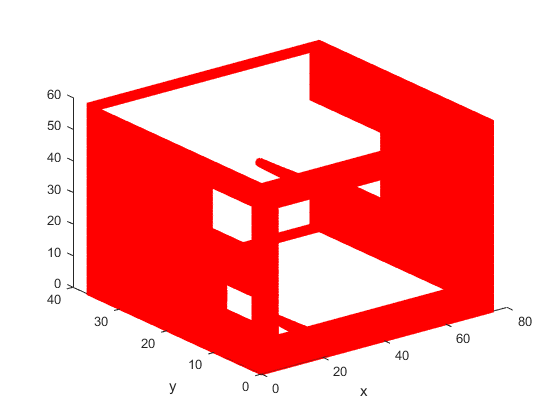


% Show
figure(4)

for i = 0:sliceHeight:double(max(op(:,3)))
    
    zPlotPoints = op(op(:,3) == i,:);
    
    for j = 1:max(zPlotPoints(:,4))
    
        pathPlotPoints = zPlotPoints(zPlotPoints(:,4) == j,:);
        plot3(pathPlotPoints(:,1), pathPlotPoints(:,2), pathPlotPoints(:,3),'-r','LineWidth',2);
        hold on

    end

end

xlabel('x')
ylabel('y')
view(3);
hold on